# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 1;
KiStatic = 10;
tdStatic=0.04;

# Toggles

togRMSFreq = 1;

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

load_system(simName)


Simulink startup was interrupted. To ensure that Simulink is ready
 to use, run sl_refresh_customizations before opening a model.



ans =     'Error using slCustomizer.staticRefresh
     Program interruption (Ctrl-C) has been detected.'


Error using load_system (line 21)
Model 'HybridSaccadeFF' was created with a newer version (R2020a) of Simulink
To disable this error message, use Simulink preferences.
To create a model that is compatible with this version of Simulink, load the model in Simulink R2020a and select File > Export Model to > Previous Version.

set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize,'FastRestart','on') %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# RMSE as a function of frequency and switching threshold

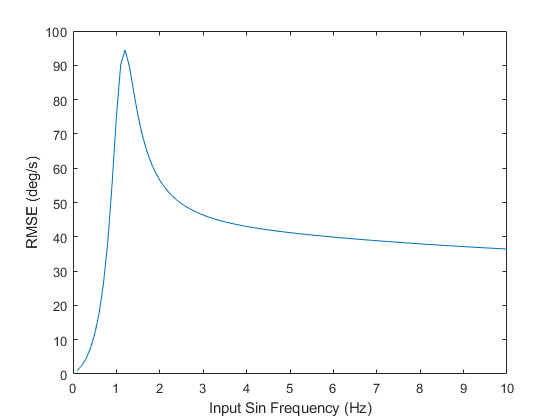

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = KpStatic;
    Ki = KiStatic;
    td =tdStatic;
    smoothRMSE = simRMSE(Kp,Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[]);
    
    %Next, Hybrid System with Infinite switching threshold (should match
    %pure smooth system)
    tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
    hybridInfRMSE = simRMSE(Kp,Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet);
    
    figure
    plot(sinfreqs,smoothRMSE,sinfreqs,hybridInfRMSE)
    lgd({1}) = 'Smooth Lsim';
    lgd({2}) = 'Smooth Simulink';
    hold on
    switchThreshRange = [0 0.05 0.1 0.5 1 5]
    for i = 1:length(switchThreshRange)
        hybridTempRMSE = simRMSE(Kp,Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet);  
        plot(sinfreqs,hybridTempRMSE)
        lgd({2+i}) = strcat('Hybrid - Switch Threshold = ',num2str(switchThreshRange(i)))
    end
    
    xlabel('Input Sin Frequency (Hz)')
    ylabel('RMSE (deg/s)')
    legend(lgd)
    hold off   
end

# Sweep across switching threshold

%Input
V_in = [t' sos'];

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper
K_P = 6; %Proportional Gain
K_I = .05; %Integral Gain of smooth system


switch_threshbig = 0.01:0.01:5; %Integrated error threshold for switching between smooth/saccadic
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    soserrorsingle(i) = sum(abs(sos'-out.V_out));
end

figure
plot(switch_threshbig,normalize(soserrorsingle,'range'))
hold on

%Input
V_in = [t' chirps'];
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    chirpserrorsingle(i) = sum(abs(chirps'-out.V_out));
end

plot(switch_threshbig,normalize(chirpserrorsingle,'range'))

K_P = 3; %Proportional Gain

V_in = [t' sos'];
switch_threshbig = 0.01:0.01:5; %Integrated error threshold for switching between smooth/saccadic
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    soserrorsingle(i) = sum(abs(sos'-out.V_out));
end

plot(switch_threshbig,normalize(soserrorsingle,'range'))

%Input
V_in = [t' chirps'];
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    chirpserrorsingle(i) = sum(abs(chirps'-out.V_out));
end

plot(switch_threshbig,normalize(chirpserrorsingle,'range'))
ylabel('Normalized Error')
xlabel('Switching Threshold')
legend('SoS Error, K_p = 6','Chirp Error, K_p = 6','SoS Error, K_p = 3','Chirp Error, K_p = 3')

# Optimal Point Gain Sweep

Prange = 1:1:15;
Irange = 1:1:15;
switchrange = 0.5:0.5:10;
freqrange = 1:1:5;
estimatedTimeHrs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/3600
estimatedTimeMins = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/60
estimatedTimeSecs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/1

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper

%Input
%V_in = [t' sos'];

% %Parallel Simulation Setup
% tic
% numSims = size(switchrange,2)*size(Prange,2)*size(Irange,2);
% clear simIn
% simIn(1:numSims) = Simulink.SimulationInput(simName);
% 
% iter = 1;
% for i = 1:size(Prange,2)
%     for j = 1:size(Irange,2)
%         for k = 1:size(switchrange,2) 
%             %Constants
%             simIn(iter) = simIn(iter).setVariable('sac_time',sac_time,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('n_delay',n_delay,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_up',T_lim_up,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_low',T_lim_low,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('G_plant',G_plant,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('V_in',V_in,'Workspace',simName);
%             
%             %Variables
%             simIn(iter) = simIn(iter).setVariable('switch_thresh',switchrange(k),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_P',Prange(i),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_I',Irange(j),'Workspace',simName);
%             
%             iter = iter + 1;
%         end
%         
%     end
% end
% out = parsim(simIn,'UseFastRestart','on');
% toc

tic
minswitch = zeros(size(freqrange,2),size(Prange,2)*size(Irange,2),3);
error = zeros(1,size(switchrange,2));
iter=1;
for l = 1:size(freqrange,2)
   puresine = 50*sin(2*pi*freqrange(l)*t);
   V_in = [t' puresine'];
   for i = 1:size(Prange,2)
    for j = 1:size(Irange,2)
        K_P = Prange(i);
        K_I = Irange(j);

        for k = 1:size(switchrange,2)
            switch_thresh = switchrange(k);
            out = sim('HybridSaccadeFF.slx');
            error(k) = sum(abs(sos'-out.V_out));
        end
        
        [minerror,index] = min(error);
        minswitch(l,iter,:) = [K_P K_I switchrange(index)];
        iter=iter+1;
    end  
    end 
end

toc

filename1 = strcat('ch','_',num2str(scale),'_',num2str(f_start),'_',num2str(f_end),'_');
filename2 = strcat('ssf','_',num2str(f(1)),'_',num2str(f(2)),'_',num2str(f(3)),'_');
filename3 = strcat('ssp','_',num2str(p(1)),'_',num2str(p(2)),'_',num2str(p(3)),'_');
filename4 = strcat('kp','_',num2str(Prange(1)),'_',num2str(Prange(2)-Prange(1)),'_',num2str(Prange(end)),'_');
filename5 = strcat('ki','_',num2str(Irange(1)),'_',num2str(Irange(2)-Irange(1)),'_',num2str(Irange(end)),'_');
filename6 = strcat('sw','_',num2str(switchrange(1)),'_',num2str(switchrange(2)-switchrange(1)),'_',num2str(switchrange(end)));
filename7 = strcat('sw','_',num2str(freqrange(1)),'_',num2str(freqrange(2)-freqrange(1)),'_',num2str(freqrange(end)));
filename = strcat(filename1,filename2,filename3,filename4,filename5,filename6,'.mat')
save(filename,'minswitch','chirps','sos','scale')


for i = 1:size(freqrange,2)
    figure('Renderer', 'painters', 'Position', [10 10 1000 700])
    set(gcf, 'Color', 'w');
    sf = fit([minswitch(i,:,1)', minswitch(i,:,2)'],minswitch(i,:,3)','cubicinterp');
    plot(sf)
end




ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Optimum Switching Threshold','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-30,25)
